clc
clear

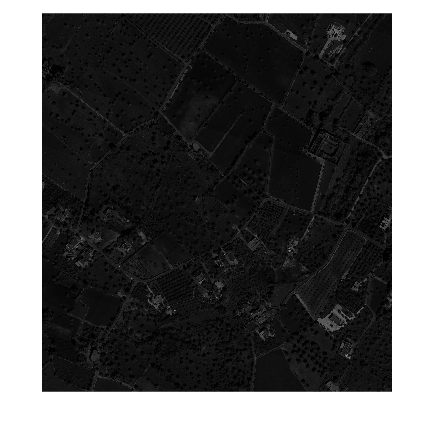

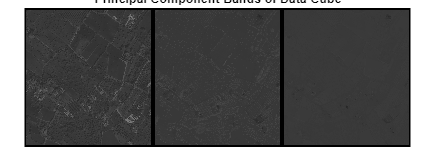

% Loading image
image_path = 'CROP1_47.tiff';
hcube = imread(image_path);

% Calculating PCA
[image,components] = PCA(hcube,5);

% k-medoids clustering
num_clusters = 5;

% Reshaping image
pixels = reshape(image, [], size(image, 3));

% Set options
opts = statset('Display','final','MaxIter',100);

% Run k-medoids
[idx,centers] = kmedoids(pixels,num_clusters,'Options',opts);

Best total sum of distances = 60130.9


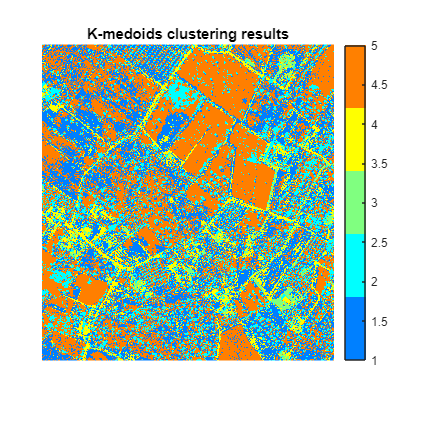


% Obtaining image's sizes
[rows, cols, ~] = size(image);

% Plot results
figure;
imshow(reshape(idx, [rows, cols]), []);
colormap(jet(num_clusters));
colorbar;
title('K-medoids clustering results');